
afin1 = abs(fin1(257:-1:1,:));
lfin1 = log(abs(fin1(257:-1:1,:))+0.0001);

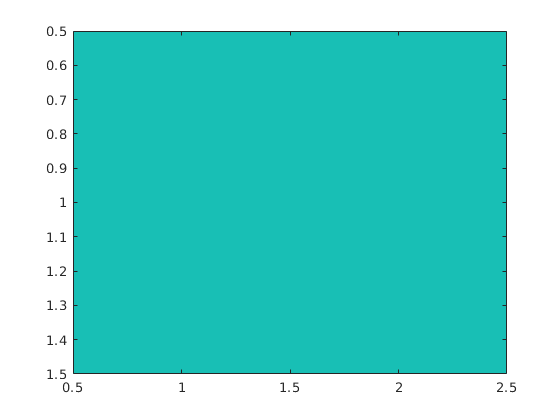

kn = ones(1,2);
%kn(2,5) = 1;
[dfin1 k] = deconvblind(afin1, kn, 1, 30);
imagesc(k)

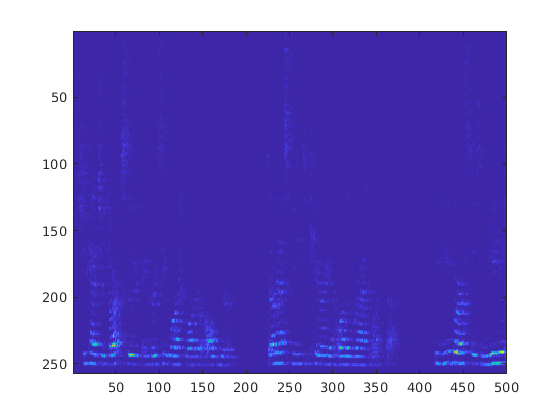

imagesc(dfin1)

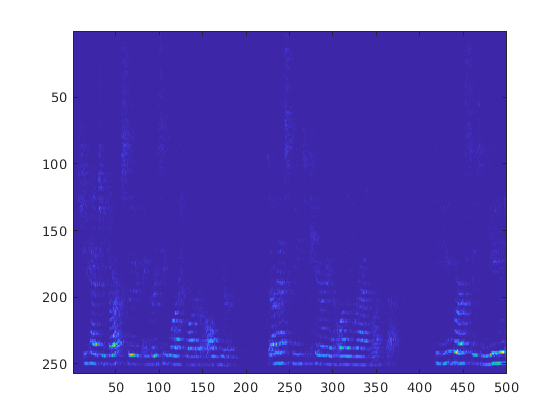

dyfin1 = deconvlucy(afin1,k,1);
imagesc(dyfin1)

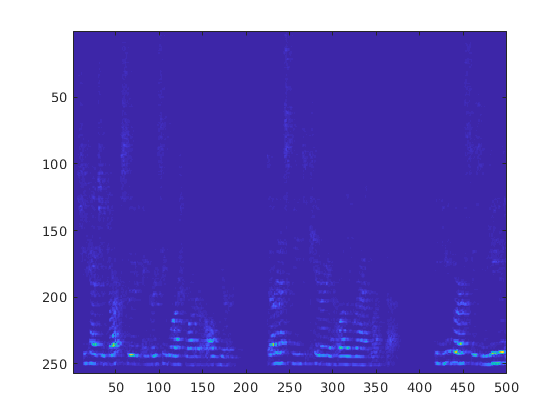

cdyfin1 = conv2(dyfin1,k,'same');
imagesc(cdyfin1)

imagesc(afin1)

r = [afin1(:, :); afin1(end-1:-1:2, :)];

Undefined function or variable 'afin1'.

sound = stftsynthesis(r', cfg.fft_size, cfg.shift);

player = audioplayer(sound, fs);
play(player)